%% Import data from text file
% Script for importing data from the following text file:
%
%    filename: D:\scope_0.csv
%
% Auto-generated by MATLAB on 17-Feb-2023 15:27:19


## Set up the Import Options and import the data


opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["VarName1", "FrequencyHz", "AmplitudeVpp", "GaindB", "Phase"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
scope0 = readtable("D:\scope_0.csv", opts);



## Clear temporary variables


clear opts
R1 = 62.4;
R2 = 325.25;
C1 = 1.04*10^-6;
C2 = 1.04*10^-6;

G= [1, 0, 0
    -1/R1, 1/R1+1/R2, -1/R2
    0 ,-1/R2 ,1/R2];

C= [0,C1,0; 0,C1,0; 0,0,C2];

b= [1;0;0];

r=[1 2 3 4 5 6 7 8 9];
w=[r (10*r) (1e2*r) (1e3*r) (1e4*r) (1e5*r)];
freq = w/(2*pi)

freq = 	1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0011    0.0013    0.0014    0.0016    0.0032    0.0048    0.0064    0.0080    0.0095    0.0111    0.0127    0.0143    0.0159    0.0318    0.0477    0.0637    0.0796    0.0955    0.1114    0.1273    0.1432    0.1592    0.3183    0.4775    0.6366    0.7958


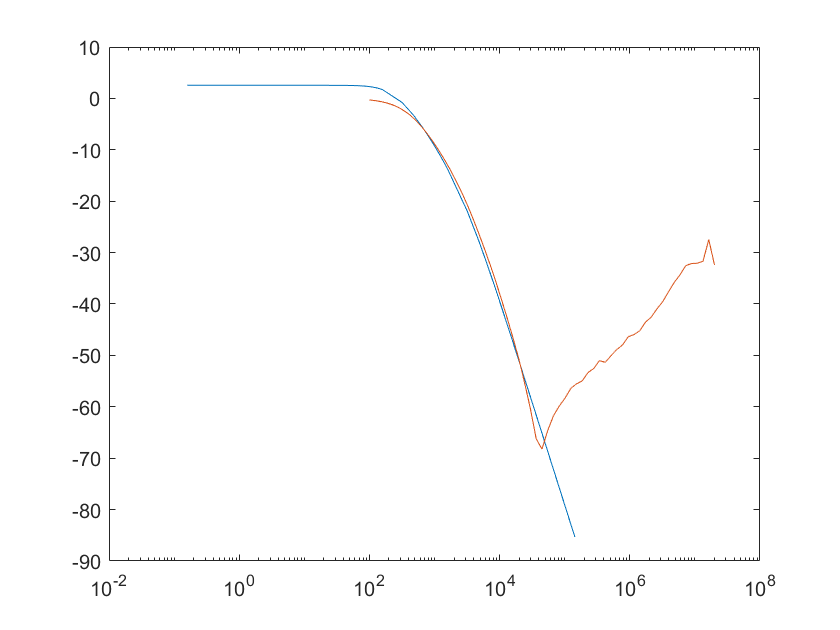


% freqresp4



x= scope0.FrequencyHz;
y=scope0.GaindB;

semilogx(freq, freqresp4(G, C, b, w))
grid
hold on
semilogx(x,y)
grid
hold off

function Q=variation(R)
m=length(R);
g=ones(1,m)+0.5*rand(1,m);
Q=0.8*(R.*g);
end

function F = freqresp4(G, C, b, w)

mag = zeros(3,1);

    for k=1:length(w)
        omega = w(k);
        A = G+i*omega*C+(1/(i*omega));
        x=A\b;
        
        mag = [mag abs(x)];
    end
    
    V3 = mag(3,2:length(w)+1);
    F=20*log10(V3);


end 
 